## Functions

#### Get Feature Matric

function features = Features(data, d)
    % Function to create a table of features from data
    
    % Get the column names
    cols = data.Properties.VariableNames;
    
    % Create the list of monomials. We consider non-constant elements.
    coeffs = GenerateCoeffs(length(cols), d);
    coeffs(1,:) = []; % Remove the first entry (constant term)
    
    % Initialize a struct to hold features
    features_struct = struct();
    
    % Loop through each coefficient and calculate the corresponding feature
    for idx = 1:size(coeffs, 1)
        coef = coeffs(idx, :);
        column_name = strrep(mat2str(coef),' ','_');
        column_name = strrep(column_name,'[','c_');
        column_name = strrep(column_name,']','');
        col_value = ones(height(data), 1);
        
        for j = 1:length(coef)
            col_value = col_value .* (data{:, j}.^coef(j));
        end
        
        % Store the feature in the struct
        features_struct.(column_name) = col_value;
    end
    
    % Convert the struct to a table
    features = struct2table(features_struct);
end

function coeffs = GenerateCoeffs(num_vars, degree)
    % Recursive function to generate coefficients
    if num_vars == 1
        coeffs = (0:degree)';
    else
        coeffs = [];
        for i = 0:degree
            sub_coeffs = GenerateCoeffs(num_vars - 1, degree - i);
            coeffs = [coeffs; [i * ones(size(sub_coeffs, 1), 1), sub_coeffs]];
        end
    end
end

#### Get Random Feature Sample

function [low, high, sample] = get_Random_Feature_Sample(data,d, n)
    low = min(table2array(data));
    high = max(table2array(data));
    sample = bsxfun(@plus, low, bsxfun(@times, (high - low), rand(n, length(low))));
    
    % Assuming M is a table with the desired column names
    column_names = data.Properties.VariableNames;
    
    % Convert the sample matrix to a table and assign column names
    sample_table = array2table(sample, 'VariableNames', column_names);

    sample = table2array(Features(sample_table, d));

end

#### Get c

function c = get_c(mu, Sigma, low, high, Random_Feature_Sample)
    % Calculate the multivariate t-distribution PDF values for the sample
    z = mvnpdf(Random_Feature_Sample, mu, Sigma);
    
    % Compute the volume of the integration range
    vol = prod(high - low);
    
    % Calculate the output
    c = vol * mean(z);
end

#### Get Log-Likelihood

function [L] = get_log_likelihood(mu,Sigma,c,Features)
    l = mvnpdf(Features, mu, Sigma)/c;
    l(l<10e-23) = 10e-23;
    L = sum(log(l));
end

function [l] = Estimated_pdf(mu,Sigma,c,Features)
    l = mvnpdf(Features, mu, Sigma)/c;
end

#### Feature Space Estimates

function [mu, Sigma] = get_Feature_Space_Estimates(data, d)
    % Calculate the feature matrix using the Features function
    mat = Features(data, d);
    
    % Compute the mean vector of the features
    mu = mean(table2array(mat), 1);
    
    % Compute the covariance matrix of the features
    Sigma = cov(table2array(mat));
end

#### Create optim vector 

function [x] = optim_vector(mu,Sigma)
    A = chol(Sigma);
    m  = triu(true(size(A)));
    v  = A(m);
    x = [mu,v.'];
end

function [mu,Sigma] = revert_optim_vector(x,D)
    mu = x(1:D);
    v = x(D+1:length(x));
    M = zeros(D,D);
    M(triu(true(D))) = v;
    Sigma = M.'*M;
end

#### Create Function to be Optimized

function [obj] = get_obj(v,Feature_matrix,D,low,high,Random_Feature_Sample,c_bound)
    [mu,Sigma] = revert_optim_vector(v,D);

    c =  get_c(mu,Sigma, low, high,Random_Feature_Sample);
    if c<c_bound
        c = c_bound;
    end
    L = get_log_likelihood(mu,Sigma,c,Feature_matrix);
    obj = -L;

end

#### Get Data Space Estimates


function [mu, Sigma] = get_optim(data,d,low,high, Random_Feature_Sample, c_bound)
    [mu_0, Sigma_0] = get_Feature_Space_Estimates(data, d);
    v_0 = optim_vector(mu_0,Sigma_0);
    D = length(mu_0);

    Feature_matrix = table2array(Features(data, d));
    options = optimoptions('fmincon');
    options.MaxFunctionEvaluations = 50000;
    options.OptimalityTolerance = 1.0e-4;
    options.StepTolerance = 1.0e-5;
    options.Display = 'iter';


    
    lb = [ones(length(v_0),1)].*(-10);
    lb(1:D) = -100;
    ub = [ones(length(v_0),1)].*(10);
    ub(1:D) = 100;

    v = fmincon(@(v) get_obj(v,Feature_matrix,D,low,high,Random_Feature_Sample,c_bound), v_0, [],[],[],[],lb,ub,[],options);
    [mu, Sigma] = revert_optim_vector(v,D);
end


#### Plotting Helper

function mesh = mesh_3D(low,high, mu, Sigma, c, d)
        % Generate the x-axis and y-axis points
    xaxis = linspace(low(1), high(1), 100);
    yaxis = linspace(low(2), high(2), 100);
    zaxis = linspace(low(3), high(3), 100);
    % Create the meshgrid
    [x, y, z] = meshgrid(xaxis, yaxis, zaxis);
    
    % Reshape the grid matrices into column vectors
    x_col = x(:);
    y_col = y(:);
    z_col = z(:);
    
    % Create the table `mesh` with the reshaped x and y values
    mesh = table(x_col, y_col, z_col);
    
    % Calculate the feature matrix for the mesh
    features_mesh = table2array(Features(mesh, d));
    
    % Compute pdf 
    mesh.pdf = Estimated_pdf(mu,Sigma,c,features_mesh);
end


function get_contour_from_mesh(data, mesh, shape, titleText, xLabel, yLabel)
    % Default parameter values if not provided
    if nargin < 4
        titleText = 'Bivariate Data with Estimated PDF Contours';
    end
    if nargin < 5
        xLabel = 'X-axis';
    end
    if nargin < 6
        yLabel = 'Y-axis';
    end
    
    % Plot the scatter plot of the bivariate data
    RGB = [255,192,203]/256;
    scatter(data{:,1}, data{:,2}, 5, RGB, 'filled'); % Using a size of 5 for better visibility
    hold on;

    % Extract X, Y, Z from mesh and reshape according to the shape
    X = reshape(mesh{:,1}, shape);
    Y = reshape(mesh{:,2}, shape);
    Z = reshape(mesh.sum_pdf, shape);

    % Plot the contour lines of the estimated pdf
    contour(X, Y, Z); % '4' specifies 4 contour levels
    
    colorbar;
    
    % Set axis labels and title
    xlabel(xLabel);
    ylabel(yLabel);
    title(titleText);

    % Display the legend and show the plot
    legend('Data points');
    hold off;
end

## Usage

### Data 

M = readtable("dependency_data.csv");
head(M)

      X_1         X_2          X_3          X_4          X_5   
    ________    ________    _________    _________    _________

     0.26718    -0.54582     -0.63841      0.67877    -0.024864
     0.33837    -0.24397      -1.0891    -0.063481     -0.17296
    -0.84266    -0.50057      0.73294      -3.1515      -3.9448
      1.4953     0.63684      -1.8623      0.25859      0.23661
    -0.12912    -0.76427     -0.23147      -3.1103      -1.2437
     0.01045     -1.0328      0.72589       0.2631       0.6761
     0.14602     -1.3867    -0.085413       1.1372      0.33672
     0.64277    -0.33697     -0.24148      0.26941     -0.31693




M = M(:,[1 2 3]);

### Fitting

[low, high, sample] = get_Random_Feature_Sample(M,2, 100000);
c_bound = 1e-7

c_bound = 1.0000e-07

d = 2

d = 2

[mu, Sigma] = get_optim(M,d,low,high, sample, c_bound)

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      55    4.782039e+03    0.000e+00    7.921e+02
    1     117    4.645087e+03    0.000e+00    1.937e+03    9.129e-01
    2     173    4.142396e+03    0.000e+00    3.778e+02    9.104e-01
    3     234    3.951276e+03    0.000e+00    2.279e+02    4.551e-01
    4     290    3.950273e+03    0.000e+00    1.412e+03    9.119e-01
    5     351    3.836481e+03    0.000e+00    1.314e+03    4.572e-01
    6     408    3.809796e+03    0.000e+00    6.887e+02    2.273e-01
    7     467    3.798832e+03    0.000e+00    6.702e+02    4.558e-01
    8     523    3.731620e+03    0.000e+00    3.197e+02    4.553e-01
    9     583    3.610762e+03    0.000e+00    2.281e+02    4.548e-01
   10     640    3.586325e+03    0.000e+00    2.827e+02    4.548e-01
   11     700    3.533617e+03    0.000e+00    2.417e+02    4.547e-01
   12     757    3.524201e+03    0.000e+00    4

mu =    -0.2344    0.3402    0.6464   -1.0735    5.7668    0.2136    0.2796    1.6709    2.0206


Sigma =     2.2130    2.2747    0.1565    5.5872    3.4172    0.1713    0.3914    1.6166    0.3118
    2.2747   61.2513    4.4663   14.3834   23.0478   -0.7859    0.6947   -4.3490    7.3151
    0.1565    4.4663    4.0421    1.9116   20.3739    0.3557   -0.0051    3.2051    5.9204
    5.5872   14.3834    1.9116   37.9596   20.9756    0.1897    2.2182    4.8358    3.2702
    3.4172   23.0478   20.3739   20.9756  181.4644    4.5623    2.0695   37.6097   30.7589
    0.1713   -0.7859    0.3557    0.1897    4.5623    2.5573    0.9543   12.5632    0.4323
    0.3914    0.6947   -0.0051    2.2182    2.0695    0.9543    9.7284    4.4217   -0.0757
    1.6166   -4.3490    3.2051    4.8358   37.6097   12.5632    4.4217   86.4347    4.6159
    0.3118    7.3151    5.9204    3.2702   30.7589    0.4323   -0.0757    4.6159    8.9956


### Visualize

(This will only work for 3-variate data)

c = get_c(mu,Sigma, low, high,sample);
mesh = mesh_3D(low,high, mu, Sigma, c, d);

% set column pair you want to visualize: a,b for {1,2,3} 
a = 1

a = 1

b = 2

b = 2

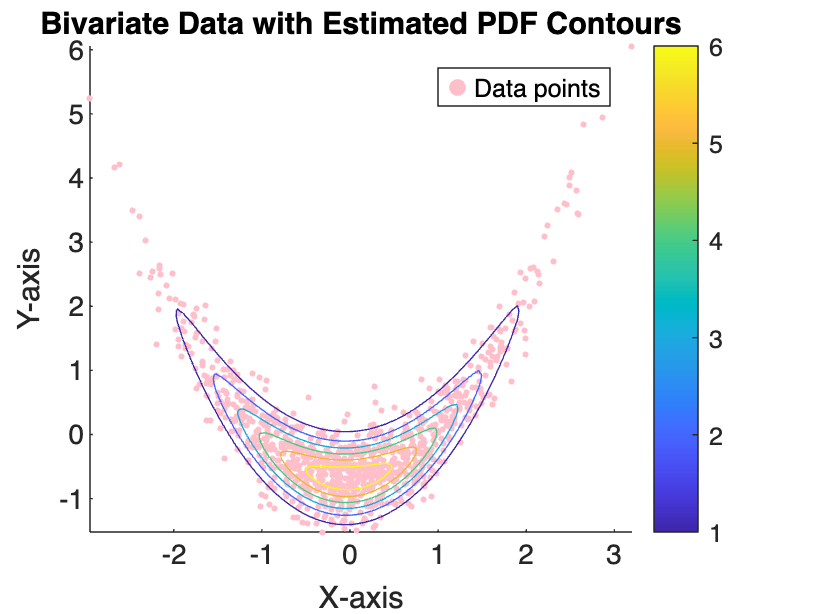


% Choose Mesh variables for contour
X = mesh.Properties.VariableNames{a}; 
Y = mesh.Properties.VariableNames{b};

% Choose Data variables for scatter

A = M.Properties.VariableNames{a}; 
B = M.Properties.VariableNames{b};

% Group the table by columns a and b and sum the 'pdf' values

grouped = groupsummary(mesh, {X, Y}, 'sum', 'pdf');
% Extract the summed 'pdf' values
summed_pdf = grouped.sum_pdf;

get_contour_from_mesh(M(:,{A,B}), grouped, [100,100])